# Optimization in MATLAB: A Practical Guide

This Live Script explains key optimization techniques in MATLAB:

- Maximization vs. Minimization

- Minimizing an External Function

- Curve Fitting

- Comparing fminsearch and fminunc

## Maximization vs. Minimization

MATLAB has two main optimizatiopn functions: `fminsearch` and `fminunc`. These functions are designed for **minimization**. To maximize a function, we minimize its negative. That is, $\max \;f\left(x\right)\equiv \min -1\times f\left(x\right)$.

**Example**: Suppose we want to find the value of $x$ that maximizes the function $f\left(x\right)=-{\left(x-3\right)}^2 +4$.


$$x^* =\underset{x}{\textrm{argmax}} -{\left(x-3\right)}^2 +4$$


Let's start by defining this function for MATLAB.

% Define a simple quadratic function f(x) = -(x-3)^2 + 4
objective_max = @(x) -(x-3).^2 + 4;       % Function to maximize. The "@(x)" tells MATLAB the arguments of the funciton
objective_min = @(x) -1*objective_max(x); % Equivalent minimization problem

% Find the maximum by minimizing the negative function
x0 = 0; % Initial guess
[x_max, fval_max] = fminsearch(objective_min, x0); % Ask MATLAB to minimize the function given the initial guess


### Visualizing the maximum

% Let's take a look at the our answer.
disp(['Maximization: x* = ', num2str(x_max), ', f(x*) = ', num2str(-fval_max)]);

Maximization: x* = 3, f(x*) = 4


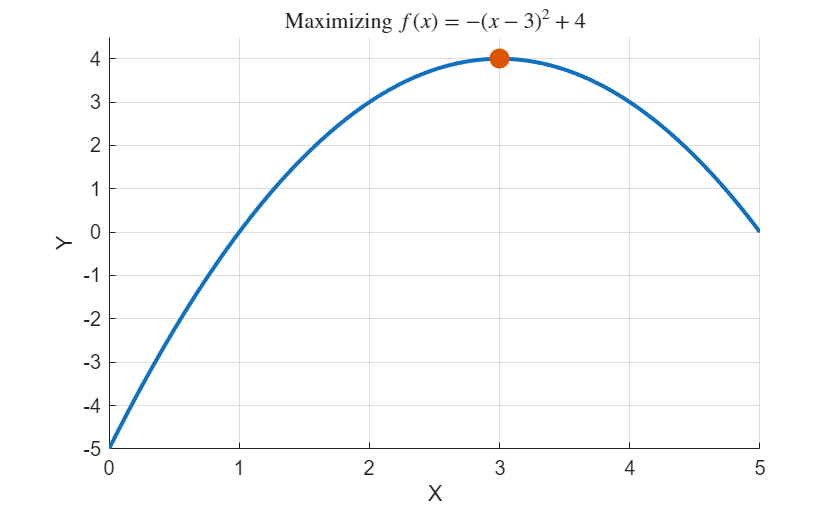


% Let's take a look at a plot of the function
x_temp = linspace(0, 5, 100);
y_temp = objective_max(x_temp);

figure
hold on
plot(x_temp,y_temp,'LineWidth',2)
scatter(x_max, -fval_max,100,"filled")
hold off
xlabel('X')
ylabel('Y')
title('Maximizing $f(x)=-(x-3)^2+4$','Interpreter','latex')
axis([0,5,-5,4.5])
grid on

## Minimizing an External Function (calling a function)

In this example, we will minimize a function defined in ``myfun.m`` using the `fminsearch` and `fminunc` commands. This approach is essential for solving GMM and MLE style problems. `fminsearch` (Nelder-Mead) is a derivative-free (grid search) optimization method, while `fminunc` uses gradients.

**Example: **Suppose we want to find the value of $x$ that minimizes the non-linear function $f\left(x\right)=\sin \left(2x\right)+0\ldotp 5x^2$. 

Given the shape of this function, changing the starting value can generate a different answer. 

% Set an initial guess
x0 = 1; % Try x0 = 3 to see how your "answer" changesX

% Find the minimum using fminsearch (derivative-free)
options = optimset('Display','iter'); % See iterations from optimizer
[x_min1, fval_min1] = fminsearch('myfun', x0, options); 

 
 Iteration   Func-count         f(x)         Procedure
     0            1           1.4093         
     1            2           1.4093         initial simplex
     2            4          1.37885         expand
     3            6          1.23045         expand
     4            8         0.609642         expand
     5           10        -0.716471         expand
     6           12        -0.716471         contract outside
     7           14         -0.74045         contract inside
     8           16        -0.752039         contract inside
     9           18        -0.752308         contract inside
    10           20        -0.753672         contract inside
    11           22        -0.753672         contract inside
    12           24        -0.753672         contract inside
    13           26        -0.753672         contract inside
    14           28        -0.753675         contract inside
    15           30        -0.753675         contract inside
    16           


% Display results
disp(['fminsearch: x* = ', num2str(x_min1), ', f(x*) = ', num2str(fval_min1)]);

fminsearch: x* = -0.62617, f(x*) = -0.75368



% Find the minimum using fminunc (gradient-based)
options = optimoptions('fminunc', 'Algorithm', 'quasi-newton','Display','iter');
[x_min2, fval_min2] = fminunc('myfun', x0, options); 

                                                        First-order 
 Iteration  Func-count       f(x)        Step-size       optimality
     0           2           1.4093                         0.168
     1          10        -0.753675        9.69696        0.00031  
     2          16        -0.753675      0.0215261       2.24e-08  

Local minimum found.

Optimization completed because the size of the gradient is less than
the value of the optimality tolerance.

<stopping criteria details>



% Display results
disp(['fminunc: x* = ', num2str(x_min2), ', f(x*) = ', num2str(fval_min2)]);

fminunc: x* = -0.62618, f(x*) = -0.75368


### Visualizing the minimum

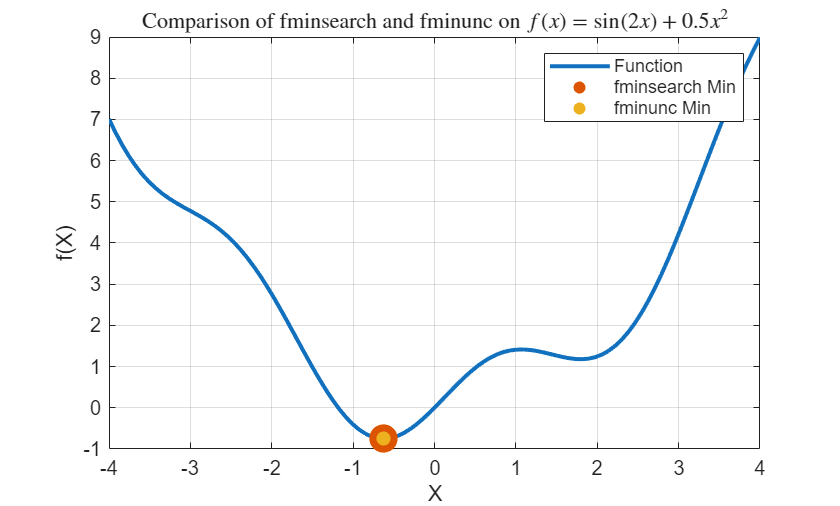

x_vals = linspace(-4, 4, 100);
y_vals = myfun(x_vals);

figure;
plot(x_vals, y_vals, 'LineWidth', 2); hold on;
scatter(x_min1, fval_min1,200,'filled','LineWidth',2);
scatter(x_min2, fval_min2, 50,'filled','LineWidth',4);
xlabel('X');
ylabel('f(X)');
title('Comparison of fminsearch and fminunc on $f(x)=\sin(2x) + 0.5x^2$','Interpreter','latex');
legend('Function', 'fminsearch Min', 'fminunc Min');
grid on;

## Curve Fitting using Nonlinear Optimization

Suppose we have noisy data and want to fit a quadratic function $f\left(x\right)={\textrm{ax}}^2 +\textrm{bx}+c+\epsilon$ where $\epsilon$ is an additively separable error term. 

% Generate pseudo-data
rng(531); % Set seed to fix draws. Comment out this line if you want different random draws. 
nobs = 100;
x_data = linspace(-5, 5, nobs)';
y_data = 2*x_data.^2 - 3*x_data + 4 + 10*randn(size(x_data)); % Quadratic with noise

We will be using a least squares approach to estimation, e.g., finding the parameters that minimize the sum of the square of the residuals. 


$$\underset{\widehat{\;a} ,\widehat{\;b} ,\widehat{\;c} }{\;\min } \sum_i {\left(y_i -\widehat{a} {x_i }^2 -\widehat{\;b} x_i -\widehat{\;c} \right)}^2$$


% Define the error function for curve fitting
error_func = @(params) sum((y_data - params(1)*x_data.^2 - params(2)*x_data - params(3)).^2);

% Optimize using fminsearch
params0 = [1, 1, 1]; % Initial guesses
optimal_params = fminsearch(error_func, params0); % vector of parameter estimates


### Visualizing the fit

disp('Optimal parameters for curve fitting:');

Optimal parameters for curve fitting:


disp(['ahat = ', num2str(optimal_params(1)), ', bhat = ', num2str(optimal_params(2)), ', chat = ', num2str(optimal_params(3))]);

ahat = 2.1334, bhat = -2.97, chat = 3.8119


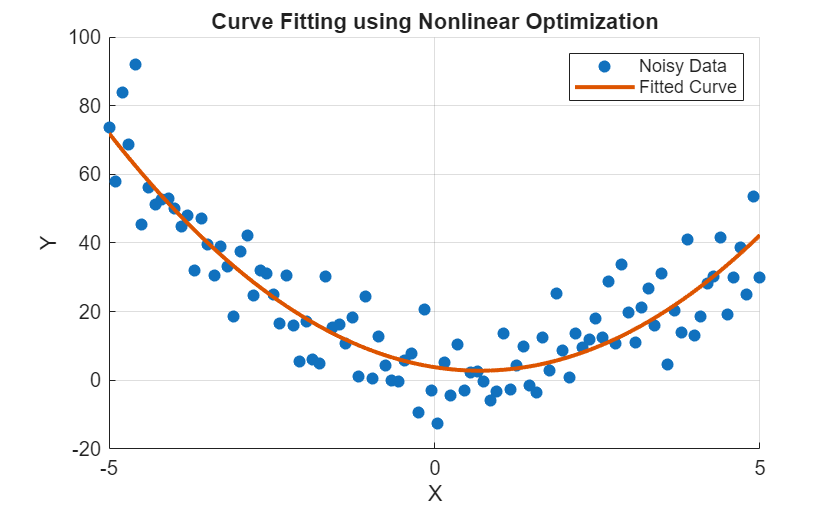


% Plot results
figure;
hold on;
scatter(x_data, y_data,'filled'); 
plot(x_data, optimal_params(1)*x_data.^2 + optimal_params(2)*x_data + optimal_params(3), 'LineWidth', 2);
hold off
xlabel('X'); ylabel('Y');
title('Curve Fitting using Nonlinear Optimization');
legend('Noisy Data', 'Fitted Curve');
grid on;